# Modelo SIR tradução Luis Guilherme 20.01937-8

## Boas práticas

clear all;
close all;
clc;
global beta;
global r;
global theta0;

## Leitura de dados

T = readtable('SIRpd.csv');    % Lendo dados csv e transformando em tabela
T = table2array(T);            % Transformando tabela em array

%% Indexando cada parte da tabela para separar S R e I
Sd = T(:,1);                   
Id = T(:,2);
Rd = T(:,3);

## Gerando ruído para os dados amostrados

Sdn = 20.*randn(1000,1);

Idn = 10.*randn(1000,1);

Rdn = 20.*randn(1000,1); 

## Somando dados amostrados e ruído


Sd = Sd + Sdn;
Id = Id + Idn;
Rd = Rd + Rdn;

## Chamando modelo SIR  (Simulink)

%% Tamanho da população - N
N = 500;

%% Valores iniciais do modelo
i0 = 1;
r0 = 0;
s0 = N - i0;

%% Vetor de condições iniciais

y0 = [s0 i0 r0];

theta0 = [1e-4,1e-2]; % valores iniciais
beta = theta0(1);     % taxa de contato
r = theta0(2);        % taxa média de recuperação (in 1/dia)

%% Definição de configurações do modelo

t = linspace(0,1000,1000); %*

mdl = 'SimulacaoSIR';
load_system(mdl)
cs = getActiveConfigSet(mdl);
mdl_cs = cs.copy;
set_param(mdl_cs,'AbsTol','1e-5',...
         'SaveState','on','StateSaveName','xoutNew',...
         'SaveOutput','on','OutputSaveName','youtNew');
simOut = sim(mdl, mdl_cs);

## Visualizando a evolução da Epidemia

## (Dados amostrados x Dados modelados)

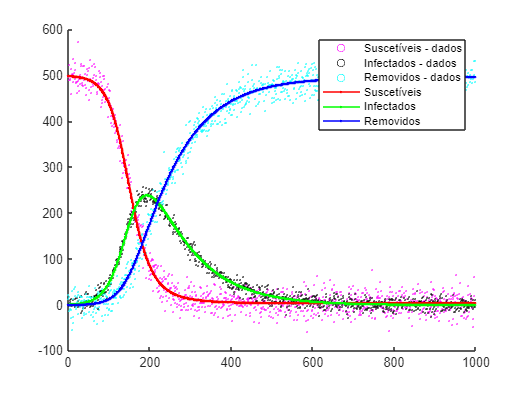

%% Saídas do modelo 
S = simOut.logsout{1}.Values.Data;  
I = simOut.logsout{2}.Values.Data;
R = simOut.logsout{3}.Values.Data;

%% Plotagem dos dados
t = linspace(0,length(S),length(S));
td = linspace(0,length(Sd), length(Sd));

figure(1)

scatter(td,Sd, 0.8, 'magenta')
hold on;
scatter(td,Id, 0.8, 'black')
scatter(td,Rd, 0.8, 'cyan')
plot(t, S, marker='.', color='r')
plot(t, I, marker='.', color='g')
plot(t, R, marker='.', color='b')


legend('Suscetíveis - dados', 'Infectados - dados', 'Removidos - dados', 'Suscetíveis', 'Infectados', 'Removidos')
xlabel = ('Dias');
ylabel = ('Indivíduos');
hold off;

## Minimizando erro

theta0 = [beta r];

X = fminsearch(@(x) ErroQuadratico(x, Sd, Rd, Id), theta0)

Eq = 8.9750e+05

Eq = 1.1717e+06

Eq = 9.1639e+05

Eq = 1.2421e+06

Eq = 9.7196e+05

Eq = 9.8313e+05

Eq = 9.1924e+05

Eq = 9.2183e+05

Eq = 9.0585e+05

Eq = 9.1708e+05

Eq = 9.0424e+05

Eq = 8.9813e+05

Eq = 9.0225e+05

Eq = 8.9787e+05

Eq = 9.0185e+05

Eq = 8.9693e+05

Eq = 8.9830e+05

Eq = 8.9705e+05

Eq = 8.9846e+05

Eq = 8.9692e+05

Eq = 8.9695e+05

Eq = 8.9683e+05

Eq = 8.9724e+05

Eq = 8.9681e+05

Eq = 8.9710e+05

Eq = 8.9682e+05

Eq = 8.9683e+05

Eq = 8.9680e+05

Eq = 8.9687e+05

Eq = 8.9680e+05

Eq = 8.9682e+05

Eq = 8.9680e+05

Eq = 8.9680e+05

Eq = 8.9681e+05

Eq = 8.9681e+05

Eq = 8.9680e+05

Eq = 8.9680e+05

Eq = 8.9680e+05

Eq = 8.9680e+05

Eq = 8.9680e+05

Eq = 8.9680e+05

Eq = 8.9680e+05

Eq = 8.9680e+05

Eq = 8.9680e+05

Eq = 8.9680e+05

Eq = 8.9680e+05

Eq = 8.9680e+05

Eq = 8.9680e+05

Eq = 8.9680e+05

Eq = 8.9680e+05

Eq = 8.9680e+05

Eq = 8.9680e+05

Eq = 8.9680e+05

Eq = 8.9680e+05

Eq = 8.9680e+05

Eq = 8.9680e+05

Eq = 8.9680e+05

Eq = 8.9680e+05

Eq = 8.9680e+05

Eq = 8.9680e+05

Eq = 8.9680e+05

Eq = 8.9680e+05

Eq = 8.9680e+05

Eq = 8.9680e+05

Eq = 8.9680e+05

X =     0.0001    0.0100


beta = X(1);
r = X(2);

## Visualizando modelo ajustado em comparação com dados reais

%%% Saídas do modelo

mdl = 'SimulacaoSIR';
load_system(mdl)
cs = getActiveConfigSet(mdl);
mdl_cs = cs.copy;
set_param(mdl_cs,'AbsTol','1e-5',...
         'SaveState','on','StateSaveName','xoutNew',...
         'SaveOutput','on','OutputSaveName','youtNew');
simOut = sim(mdl, mdl_cs);

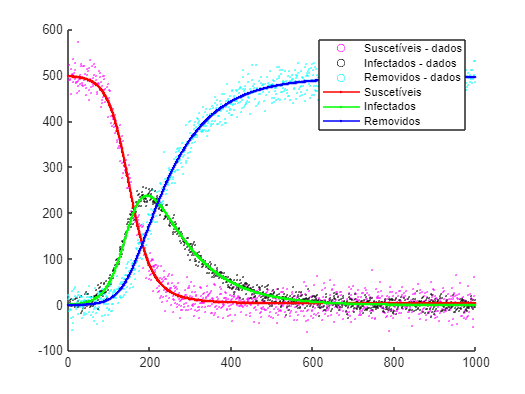


S = simOut.logsout{1}.Values.Data;  
I = simOut.logsout{2}.Values.Data;
R = simOut.logsout{3}.Values.Data;

%% Plotagem dos dados
t = linspace(0,length(S),length(S));
td = linspace(0,length(Sd), length(Sd));

figure(2)

scatter(td,Sd, 0.8, 'magenta')
hold on;
scatter(td,Id, 0.8, 'black')
scatter(td,Rd, 0.8, 'cyan')
plot(t, S, marker='.', color='r')
plot(t, I, marker='.', color='g')
plot(t, R, marker='.', color='b')


legend('Suscetíveis - dados', 'Infectados - dados', 'Removidos - dados', 'Suscetíveis', 'Infectados', 'Removidos')
xlabel = ('Dias');
ylabel = ('Indivíduos');
hold off;